clear
clf
load("Lab3\Experiment 1\Vin.mat")
load("Lab3\Experiment 1\Iout_ch2.mat")
load("Lab3\Experiment 1\Iout_ch1.mat")
Ve=0;
start_time=1;
end_time=190;
Ie=-Iout_ch2(:,start_time:end_time);
Ib=Iout_ch1(:,start_time:end_time);
Vin=Vin(:,start_time:end_time);
Ic=Ie-abs(Ib);
%line of best fit
[first, last, mmax, bmax, Nmax]=linefit(Vin,log(Ic), 5e-6)

first = 114

last = 136

mmax = 38.0363

bmax = -32.7182

Nmax = 23

 Is = exp(bmax)

Is = 6.1754e-15

 Ut = 1/mmax

Ut = 0.0263

 Ic_theory=Is*exp((Vin-Ve)/Ut);
 [first, last, mmax, bmax, Nmax]=linefit(Vin, log(Ib), 1e-5);
B =Is/exp(bmax)

B = 162.4044

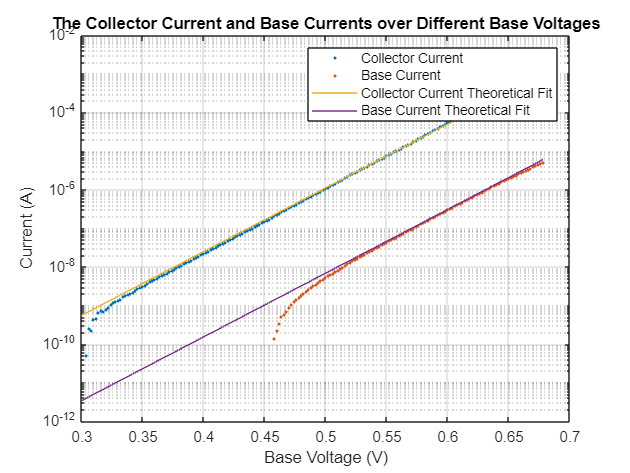

 Ib_theory=Is/B*exp((Vin-Ve)/Ut);
semilogy(Vin,Ic,'.',Vin,Ib,'.',Vin,Ic_theory,Vin,Ib_theory)
%semilogy(Vin,Ib,'.',Vin,Ic_theory,Vin,Ib_theory)
grid on
title("The Collector Current and Base Currents over Different Base Voltages")
legend('Collector Current','Base Current','Collector Current Theoretical Fit','Base Current Theoretical Fit')
ylabel("Current (A)")
xlabel("Base Voltage (V)")

clf

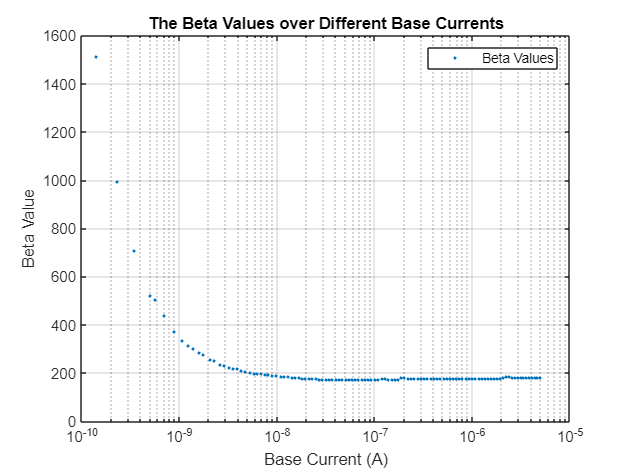

semilogx(Ib,Ic./Ib,'.')
grid on
title("The Beta Values over Different Base Currents")
legend("Beta Values")
ylabel("Beta Value")
xlabel("Base Current (A)")

clf

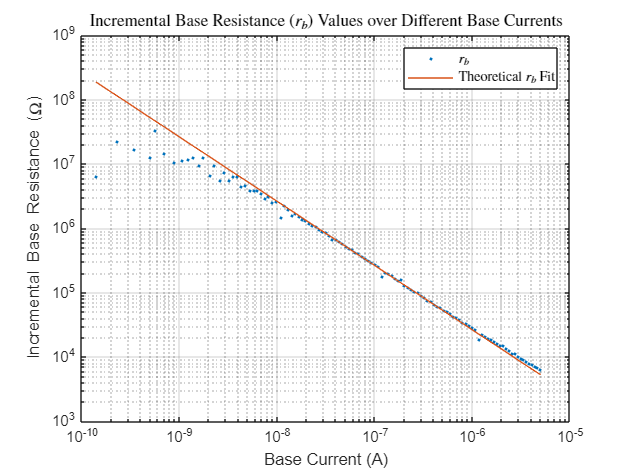

dVbdIb = [0;diff(Vin(:))./diff(Ib(:))];
loglog(Ib,dVbdIb,'.',Ib,Ut./Ib)
grid on
title("Incremental Base Resistance ($r_b$) Values over Different Base Currents","Interpreter","latex")
legend("$r_b$","Theoretical $r_b$ Fit","Interpreter","latex")
ylabel("Incremental Base Resistance (\Omega)")
xlabel("Base Current (A)")

clf

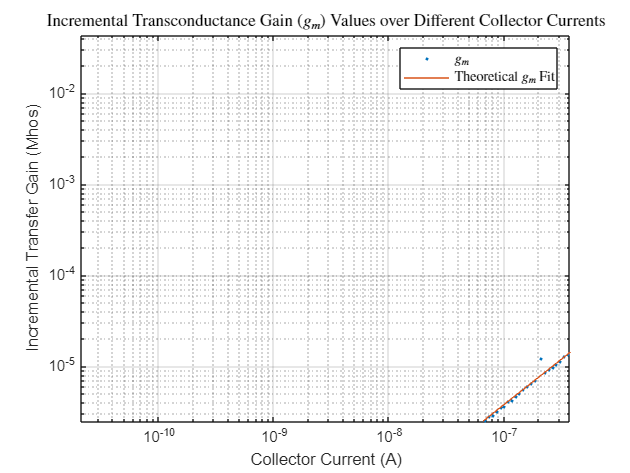

dIcdVb = [0;diff(Ic(:))./diff(Vin(:))];
loglog(Ic,dIcdVb,'.',Ic, Ic/Ut)
grid on
title("Incremental Transconductance Gain ($g_m$) Values over Different Collector Currents","Interpreter","latex")
legend("$g_m$","Theoretical $g_m$ Fit","Interpreter","latex")
ylabel("Incremental Transfer Gain (Mhos)")
xlabel("Collector Current (A)")